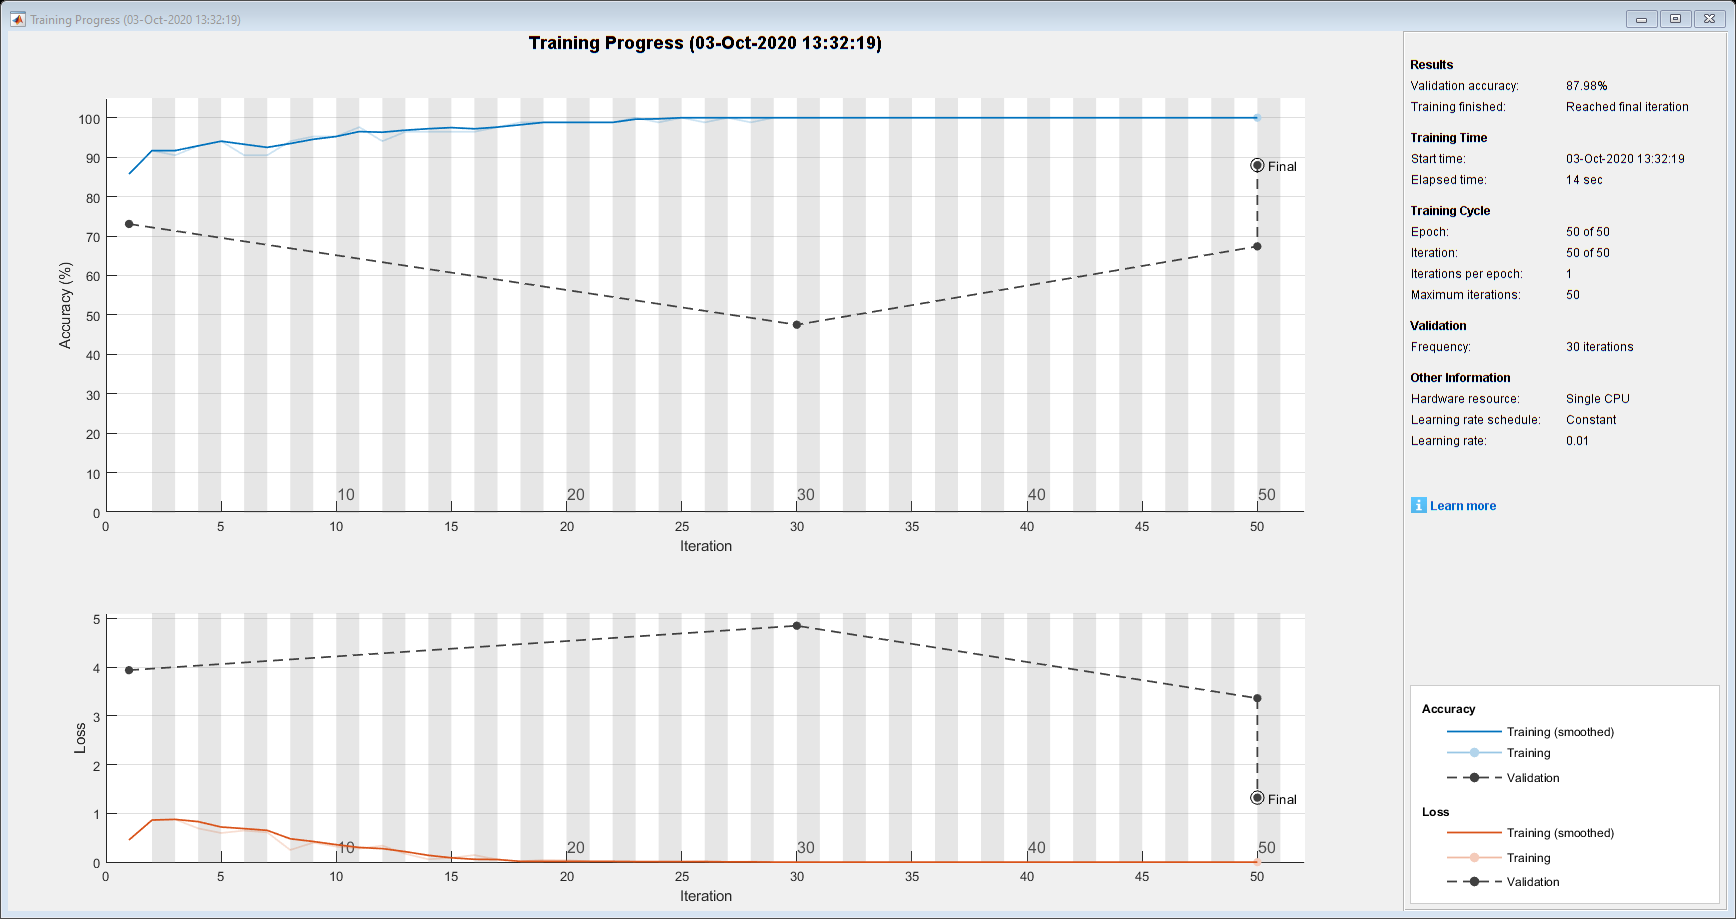

% param
numTrainFiles = 42;

% param unlikely to change
digitDatasetPath = [pwd '/Training'];
inputSize = [cproxpixel*2+1 cproxpixel*2+1 1];
numClasses = 2;

% load labels from folder names
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

% train-test split
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

% more param
layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(15,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'MaxEpochs',50, ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

% train model 'net'
net = trainNetwork(imdsTrain,layers,options);

% save net;
% load net;

% test
YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.8798